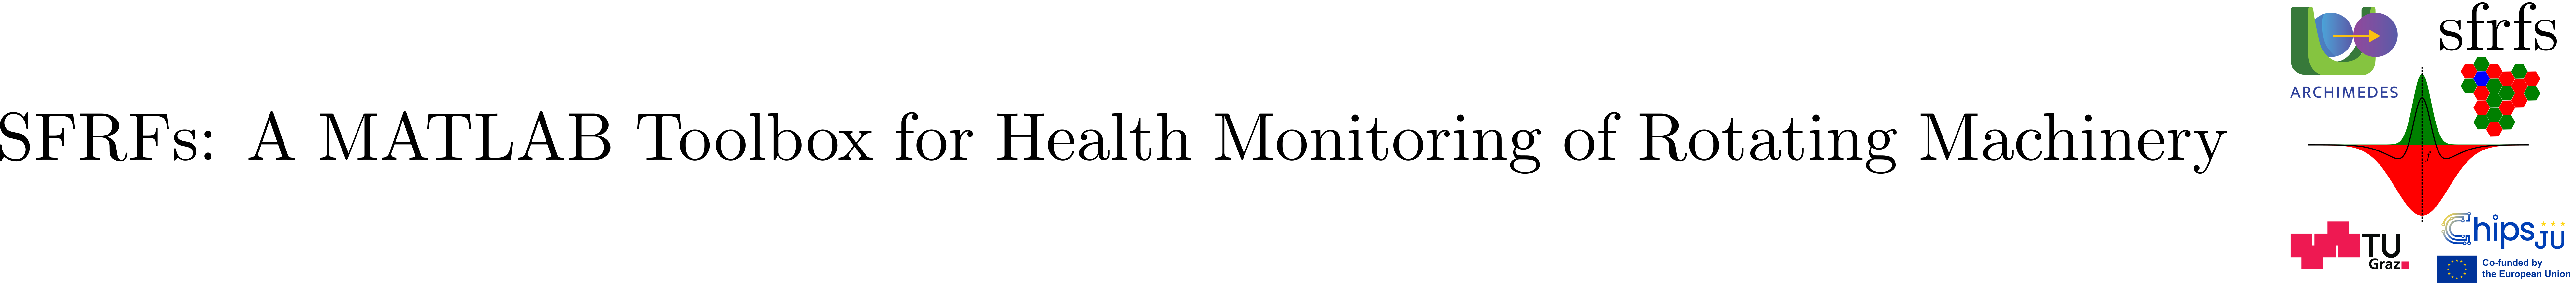

# ReceptiveFieldGainFunctions

## Summary

`ReceptiveFieldGainFunctions` is a handle class that computes frequency-domain gain functions for Spectral Fault Receptive Fields based on precomputed fault frequency bands. It transforms band definitions into  frequency-dependent masks suitable for spectral filtering.

**Key features:**

- Operates on a `FaultFrequencyBands` instance with precomputed band definitions.

- Generates Gaussian-based gain functions for both center and surround bands.

- Supports multiple operating conditions and fault types through row-wise processing of the bands table.

- Aggregates overlapping bands using **disjunction** defined as a pointwise maximum over magnitudes.

- Produces a structured output table containing center and surround frequency bank masks.

- Integrates user-defined SFRF parameters and embedded fault grouping logic.

This class operationalizes the spectral emphasis mechanism of the SFRFs framework and serves as a bridge between symbolic fault band definitions and numerical frequency-domain representations.

## `Description`

`ReceptiveFieldGainFunctions` computes frequency-domain gain functions for SFRFs using a precomputed `FaultFrequencyBands` instance. It converts band definitions into frequency-domain masks that can be directly applied in spectral analysis, filtering, or feature extraction pipelines.

For each operating condition and fault type contained in the associated `bandsTable`, the class generates two gain functions: a **center mask** and a **surround mask**. These masks are constructed using Gaussian profiles derived from the corresponding SFRF parameters and are evaluated over a user-defined frequency domain.

Overlapping frequency bands are combined using a max-aggregation strategy, resulting in a single consolidated mask per fault type and operating point. The resulting masks are stored in `gainFunctionsTable`, which preserves the original contextual information such as fault group, speed, and load.

This class provides the operational realization of the Spectral Fault Receptive Field concept, bridging precomputed fault frequency bands with numerical representations suitable for further signal processing and inference tasks.

**See also:** [`FaultFrequencyBands`](matlab:open('./FaultFrequencyBands.mlx')), [`BearingFrequencyBands`](matlab:open('./BearingFrequencyBands.mlx')), [`FrequencyMask`](matlab:open('./FrequencyMask.mlx')), [`SFRFsParametersRollingBearings`](matlab:open('./SFRFsParametersRollingBearings.mlx'))

### Public properties

### Public methods

#### computeGainFunctions

Computes receptive-field gain functions in the frequency domain for each fault band defined in a F`aultFrequencyBands` object.

The method generates Gaussian masks for both **center** and **surround** frequency bands and stores them in a new table (`gainFunctionsTable`). Overlapping bands are combined using a max-operator, equivalent to a fuzzy OR composition. For further details, see Reference [1].

**Syntax**

- `rfgf.computeGainFunctions(frequencyDomain)`

**Parameters**

**Output**

The function does not return a value, the result of the computation is stored in the `gainFunctionsTable`.

Each row in the table contains:

## Example

We provide an example corresponding to the XJTU-SY dataset (see Reference [2]).

### Receptive field gain functions computation

% Creates the descriptor for signal snapshots of XJTU-SY dataset
sp = ParametersSnapshot(...
        'samplingFrequency', 25600, ...
        'duration', 1.28, ...
        'stride', 60);

% Create geometric parameters of the bearing
bp = ParametersRollingBearings( ...
    numRollingElements = 8, ...
    ballDiameter = 7.92, ...
    pitchDiameter = 34.55, ...
    contactAngle = 0);

% Create shared SFRF params for all fault types
sharedParams = ...
    SFRFsParametersRollingBearings.createSFRFsParameters(...
    'order',           0, ...
    'numSidebands',    0, ...
    'numHarmonics',    2, ...
    'sigmaCenter',     [4, 1/3], ...
    'sigmaSurround',   [12, 1/3], ...
    'inhibitionFactor', 0.5 );

sfrfsParams = SFRFsParametersRollingBearings( ...
    SameForAllFaultTypes = sharedParams);

% Create operating conditions
speed = [35; 37.5; 40];
load  = [12; 11; 10];

oc = OperatingConditions(speed, load);

% Create BearingFrequencyBands object
bfb = BearingFrequencyBands( ...
    bearingParams = bp, ...
    sfrfsParams = sfrfsParams,...
    operatingConditions = oc);

% Compute fault frequency bands
bfb.computeBands();


% Create gain functions object
rfgf = ReceptiveFieldGainFunctions(bfb);

% Define frequency axis
f = sp.getFrequencyDomain();

% Compute masks
rfgf.computeGainFunctions(f);

% Access result
gainTable = rfgf.gainFunctionsTable;
disp(gainTable);

    FaultGroup       Description        Speed    Load    FrequencyBankMasks
    __________    __________________    _____    ____    __________________

        1         "Outer Race Fault"      35      12        {1×1 struct}   
        2         "Inner Race Fault"      35      12        {1×1 struct}   
        3         "Ball Fault"            35      12        {1×1 struct}   
        4         "Cage Fault"            35      12        {1×1 struct}   
        1         "Outer Race Fault"    37.5      11        {1×1 struct}   
        2         "Inner Race Fault"    37.5      11        {1×1 struct}   
        3         "Ball Fault"          37.5      11        {1×1 struct}   
        4         "Cage Fault"          37.5      11        {1×1 struct}   
        1         "Outer Race Fault"      40      10        {1×1 struct}   
        2         "Inner Race Fault"      40      10        {1×1 struct}   
        3         "Ball Fault"            40      10        {1×1 struct}   
        4  

### Visualizing the receptive field gain functions

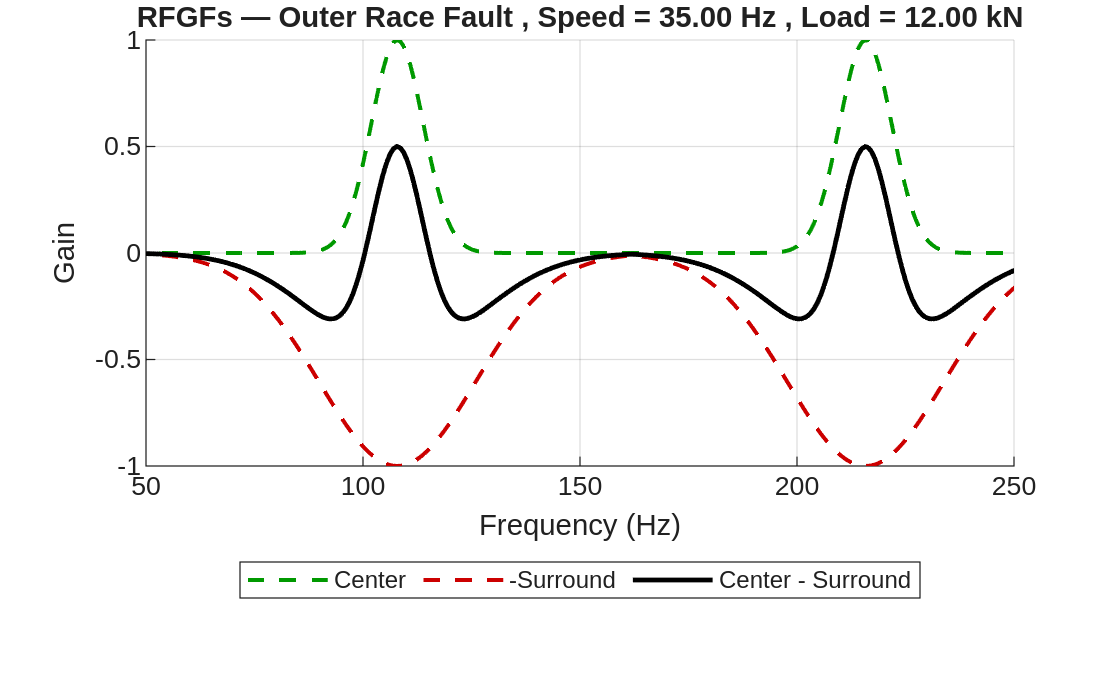

% Plot an example center gain function (first row)
plotReceptiveFieldMasks(f, gainTable, 1, [50 250],sharedParams.inhibitionFactor);

## API documentation

### MATLAB help

help ReceptiveFieldGainFunctions

  ReceptiveFieldGainFunctions  Computes receptive field gain functions
  for fault frequency bands based on provided frequencyBands.
 
    This class operates on the fault bands and parameters encapsulated
    in a FrequencyBands instance, enabling computation of Gaussian masks or 
    gain functions for Spectral Fault Receptive Fields.
 
  Properties:
    frequencyBands          - Instance of FrequencyBands containing  
                              SFRF parameters and precomputed fault bands.
 
  Example (with bearing example):
    rfgf = ReceptiveFieldGainFunctions(frequencyBandsObject);
 _
  See also BearingFrequencyBands, SFRFsParametersRollingBearings

    Documentation for ReceptiveFieldGainFunctions
       doc ReceptiveFieldGainFunctions




### MATLAB documentation

doc ReceptiveFieldGainFunctions

Opens the full class documentation in the MATLAB Help Browser, including formatted examples, links to related functions, and extended descriptions.

## Source code

The source code of this class can be found in [ReceptiveFieldGainFunctions](matlab:open('../../ReceptiveFieldGainFunctions.m')).

## Test

Unit testing for the class is implemented in [TestReceptiveFieldGainFunctions](matlab:open('../../../tests/TestReceptiveFieldGainFunctions.m')).

% execute tests
res = runtests('Spectral Fault Receptive Fields/tests/TestReceptiveFieldGainFunctions');

Running TestReceptiveFieldGainFunctions
.....
Done TestReceptiveFieldGainFunctions
__________



% display summary of tests
SFRFsTestUtil.printTestSummary(res,80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestReceptiveFieldGainFunctions/testValidConstruction                            | Passed
TestReceptiveFieldGainFunctions/testComputeGainFunctionsCreatesTable             | Passed
TestReceptiveFieldGainFunctions/testFrequencyMasksFieldsAndSize                  | Passed
TestReceptiveFieldGainFunctions/testEmptyFrequencyDomainError                    | Passed
TestReceptiveFieldGainFunctions/testComputeGainFunctionsWithZeroSidebands        | Passed



## Auxiliary functions

### Plot RFGFs

function plotReceptiveFieldMasks(f, gainTable, rowIdx, xlimRange, k)
%PLOTRECEPTIVEFIELDMASKS Plot center, surround, and difference masks
%
%   plotReceptiveFieldMasks(f, gainTable, rowIdx)
%   plotReceptiveFieldMasks(f, gainTable, rowIdx, xlimRange)
%
% Inputs:
%   f         - Frequency axis (Hz)
%   gainTable - gainFunctionsTable from ReceptiveFieldGainFunctions
%   rowIdx    - Row index to plot
%   xlimRange - (optional) [fMin fMax] for axis limits
%   k         - inhibition factor
%
% Example:
%   plotReceptiveFieldMasks(f, gainTable, 1, [50 250]);

    arguments
        f (:,1) double
        gainTable table
        rowIdx (1,1) {mustBePositive,mustBeInteger}
        xlimRange (1,2) double = []
        k (1,1) double = 0.8
    end

    if rowIdx > height(gainTable)
        error('sfrfs:plotReceptiveFieldMasks:IndexOutOfRange', ...
              'Row index exceeds table height.');
    end

    masks = gainTable.FrequencyBankMasks{rowIdx};

    centerMask   = masks.CenterFrequencyBankMask;
    surroundMask = masks.SurroundFrequencyBankMask;

    % Signed surround for visually symmetric plotting
    surroundMaskNeg = -surroundMask;

    % Difference signal
    diffMask = centerMask - k *surroundMask;

    figure; hold on;

    %% Center (green, discontinuous)
    plot(f, centerMask, ...
        'Color', [0 0.6 0], ... 
        'LineStyle', '--', ...
        'LineWidth', 1.5, ...
        'DisplayName', 'Center');

    %% Surround (negative, red, discontinuous)
    plot(f, surroundMaskNeg, ...
        'Color', [0.8 0 0], ...   
        'LineStyle', '--', ...
        'LineWidth', 1.5, ...
        'DisplayName', '-Surround');

    %% Difference (black, continuous)
    plot(f, diffMask, ...
        'Color', [0 0 0], ...
        'LineStyle', '-', ...
        'LineWidth', 1.8, ...
        'DisplayName', 'Center - Surround');

    xlabel('Frequency (Hz)');
    ylabel('Gain');

    % Get operating conditions and fault info (row 1 as example)
    speed = gainTable.Speed(rowIdx);
    load  = gainTable.Load(rowIdx);
    fault = gainTable.Description(rowIdx);

    title(sprintf( ...
        'RFGFs — %s , Speed = %.2f Hz , Load = %.2f kN', ...
        fault, speed, load));

    grid on;
    legend('show', ...
       'Location','southoutside', ...
       'Orientation','horizontal');

    if ~isempty(xlimRange)
        xlim(xlimRange);
    end

    hold off;
end

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784)

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).

- [2] Biao Wang, Yaguo Lei, Naipeng Li, Ningbo Li, “A Hybrid Prognostics Approach for Estimating Remaining Useful Life of Rolling Element Bearings”, IEEE Transactions on Reliability, pp. 1-12, 2018. [DOI: 10.1109/TR.2018.2882682](https://doi.org/10.1109/TR.2018.2882682).